clc; clear; close all;

Loading test data for pendulum drops:

load("PendTest.mat");
%Cleaning up
pendTest.data_1.angle(1:round(0.12*250)) = [];
pendTest.data_1.time(1:round(0.12*250)) = [];
pendTest.data_1.angle = pendTest.data_1.angle(:) - pendTest.data_1.angle(1) + pi;
pendTest.data_1.time = pendTest.data_1.time(:) - pendTest.data_1.time(1);

 Visualizing raw data

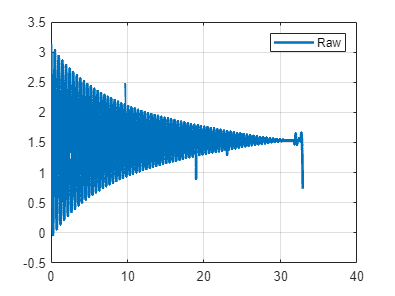

plot(pendTest.data_1.time, pendTest.data_1.angle, LineWidth=2);
legend('Raw');
grid on
box on
hold off

% Load and preprocess the data
testDataAngle = pendTest.data_1.angle(3327:6200) - 1.53398;
testDataTime = pendTest.data_1.time(3327:6200) - pendTest.data_1.time(3327);

% Plot raw data
figure;
plot(testDataTime, testDataAngle, '-.');
hold on;

% Remove outliers using moving median
[~, idx] = rmoutliers(testDataAngle, "movmedian", 0.2, "SamplePoints", testDataTime);
testDataAngleClean = testDataAngle(~idx);
testDataTimeClean = testDataTime(~idx);

% Plot cleaned data
plot(testDataTimeClean, testDataAngleClean);

% Find the peaks in the cleaned data
[~, locs] = findpeaks(testDataAngleClean);
xData = testDataTimeClean(locs);
yData = testDataAngleClean(locs);

% Plot peak points
plot(xData, yData, '*');

% Perform curve fitting using lsqcurvefit
zeta0 = -.005; % Initial random guess for zeta
theta_0 = testDataAngle(1); % Initial angle
zetaOmegan = lsqcurvefit(@(zetaOmegan0, xData) expFun(zetaOmegan0, xData, theta_0), zeta0, xData, yData)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


zetaOmegan = -0.1258

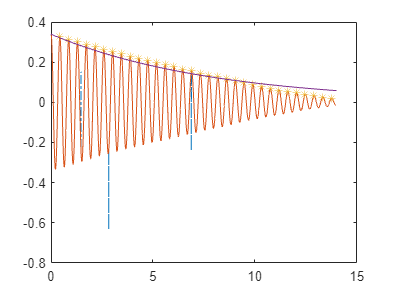


% Plot the fitted curve
plot(0:0.1:14, expFun(zetaOmegan, 0:0.1:14, theta_0));
hold off;

Create sexy plotts

Plotting paramters 

W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot

Plotting 

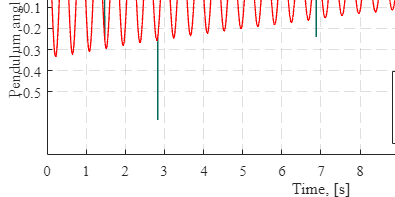

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame

hold on
plt1 = plot(testDataTime, testDataAngle, '-.');
plt1.Color = '#00695c';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-';% '-', '--', ':', '-.'
%plt1.LineStyleMode = "manual"
plt1.LineWidth  = LW1;

plt2 = plot(testDataTimeClean, testDataAngleClean);
plt2.Color = 'r';
plt2.LineStyle = '-';
plt2.LineWidth = LW1;

plt3 = plot(xData, yData, '*');
plt3.Color = '#2196f3';

plt4 = plot([0:0.1:14], expFun(zetaOmegan, [0:0.1:14], theta_0));
plt4.Color = '#5f0000';
plt4.LineWidth  = LW1;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:1:14];                    % Divisions on axes
ax.YTick = [-.5:.1:.5];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend
label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Pendulum angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];

%yaxis([ax.YTick(1) ax.YTick(end)]);

%leg = legend('Test data', 'i = k*U*(1-exp(1/tau*t)) ');
%leg = legend('Test data', '$i(t) = k \cdot U(t) \cdot (1-e^{-\frac{1}{\tau}t})$','Interpreter','latex')
leg = legend('Test data with outliners','Test data without outliners', ...
   'Peaks', '\theta_{0}\cdote^{-\zeta\cdot\omega_n t}' );
leg.Location = "southeast";

hold off
grid on
box on